## **Name: Shazzad Ahmed**

## **Student ID: 220021108**

## **Section: A2**

## **Course No: EEE 4416**

# **Assignment-06:**

**Exercise 1:**

% part 1
ju=input('Enter number of test cases: ');
for q=1:ju
    n=input('Enter an integer : ')
    draw_z(n)
end


n =

     []



ans = 1

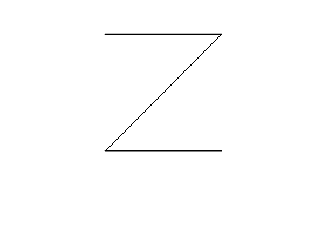

% part 2
imshow(~draw_z(100))

**Exercise 2:**

giu=input('Enter number of test cases: ');
for ii=1:giu
    n=input('Enter an integer : ')
    repeat_elem(n)
end

**Exercise 3:**

nop=input('Enter number of test cases: ');
for ii=1:nop
    n=input('give integer: ')
    goldbach(n)
end

**Exercise 4:**

calc(20, 10, "sub")

ans = 10

calc(5, 10, "div")

ans = 0.5000

calc(22, 10)

ans = 2

calc(22)

Not enough input arguments.


**Exercise 5:**

diag_dom([ 5, 0; 1, 5])

ans = 'True'

diag_dom([5, 0, 0, 10; 1, 5, 5, 10; 2, 4, 4, 5; 3, 2, 2, 1])

ans = 'False'

diag_dom([-2, 2, 1; 1, 3, 2; 1, -2, 0])

ans = 'False'

diag_dom([-4, 2, 1; 1, 6, 2; 1, -2, 5], "strong")

ans = 'True'

diag_dom([5, 0, 0; 1, 5, 2; 2, 4, 6], "strong")

ans = 'False'

diag_dom([5, 0, 0; 1, 5, 2; 2, 4, 6], "weak")

ans = 'True'

**Exercise 6:**

hmm=input('Enter number of test cases: ');
for ii=1:hmm
    a=input('Enter Array: ')
    out=knight(a)
end

**Exercise 7:**

%Test Case – 01:
repeat_elem_v2(3)

ans =      1     2     2     3     3     3


%Test Case – 02:
repeat_elem_v2(5,4)

ans =      4     4     4     4     5     5     5     5     5


%Test Case – 03:
repeat_elem_v2(1)

ans = 1

%Test Case – 04:
repeat_elem_v2(1,8)


ans =

     []



%Test Case – 05:
repeat_elem_v2(6,6)

ans =      6     6     6     6     6     6


**Exercise 1 function:**

function out=draw_z(n)
    if n<=2
        disp("N must be larger than 2.");
        return;
    end
    mat=zeros(n);
    mat(1,:)=1;
    mat(end,:)=1;
    mat(logical(flip(eye(n))))=1;
    out=mat;
end

**Exercise 2 function:**

function rslt=repeat_elem(n)
rslt=[];
for ii=1:n
    rslt=[rslt,repmat(ii,1,ii)];
end
end

**Exercise 3 function:**

function ou=goldbach(n)
    if mod(n,2)~=0
        disp("Odd numbers doesn't satisfy condition.");
        return;
    end
    p=primes(n)';
    p_half=p(p<=n/2);
    complement=n-p_half;
    mask=isprime(complement);
    ou=[p_half(mask) complement(mask)];
end

**Exercise 4 function:**

function out=calc(a,b,op)
    if nargin<2
        disp("Not enough input arguments.");
        return;
    elseif nargin<3
        op="mod";
    end
    if op=="add"
        out=a+b;
    elseif op=="sub"
        out=a-b;
    elseif op=="mul"
        out=a*b;
    elseif op=="div"
        out=a/b;
    elseif op=="mod"
        out=mod(a,b);
    end
end

**Exercise 5 function:**

function yo=diag_dom(mat, op)
    if nargin<2
        op="weak";
    end
    if op=="weak"
        o=all(abs(diag(mat))>=(sum(mat,2)-diag(mat)));
    elseif op=="strong"
        o=all(abs(diag(mat))>(sum(mat,2)-diag(mat)));
    end
    if o==1
        yo='True';
    else
        yo='False';
    end
end

**Exercise 6 function:**

function out=knight(p)
    if ~(p(1)>=1 & p(1)<=8 & p(2)>=1 & p(2)<=8)
        disp("Invalid Position.");
        return;
    end
    offset = [+2 -1;
              +2 +1;
              +1 -2;
              +1 +2;
              -2 -1;
              -2 +1;
              -1 -2;
              -1 +2;];
    valid=p+offset;
    out=valid(all(valid>=1 & valid<=8,2),:);
end

**Exercise 7 function:**

function rst=repeat_elem_v2(a,b)
rst=repeat_elem(a);
if nargin>1
    if a<b
        rst=[];
    else
        rst(rst<b)=[];
    end
end
end